# 测试(形状法)

clc
clear
close all
addpath("src\");

tof  = 506;     % days
g0   = 9.80665; % m/s^2
Isp  = 3000;    % s
Tmax = 0.4;     % N
m0   = 1000;    % kg
a_m  = 1.54067001; %AU
e_m  = 0.088373;
i_m  = 1.842622;   % deg
mu   = 132712440018; % km^3/s^2
AU   = 149597870.700; % km
e_e  = 0.0167;
p.mu = mu / AU^3;
p.tspan = 0.1 * 86400; % s
p.tf = tof * 86400; % s

r0 = [1, 0, 0]';
v0 = [0, -sqrt(p.mu / norm(r0)), 0]';
[x0, dx0] = Cart2Cylin(r0, v0)

x0 =      1
     0
     0


dx0 = 1.0e-06 *

         0
   -0.1991
         0


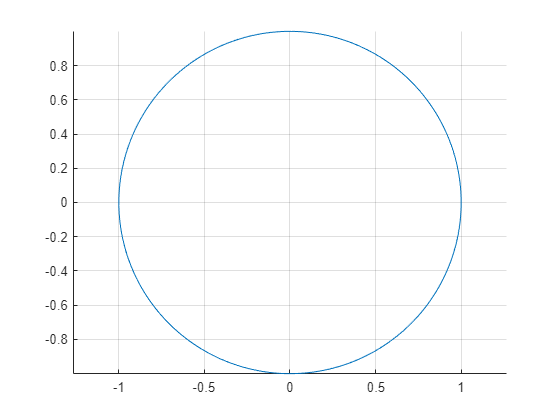

[~, s] = ode45(@(t, x) CylinEq(t, x, 0, p), 0 : p.tspan : p.tf, [x0; dx0]);
figure
hold on
plot(s(:, 1) .* cos(s(:, 2)), s(:, 1) .* sin(s(:, 2)))
grid on
axis equal